opgave 2.2 og 2.3

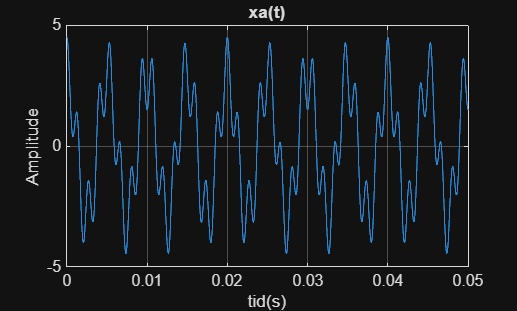


A1 = 3; %koefficient 1
A2 = 1.5; % koefficient 2 
F1 = 200; % signalfrekvens 1
F2 = 750; % signalfrekvens 2
Fs = 1000; %sampling frekvens, valgte 5000 da de opgivede ville give aliasing
N = 1e5; %antal samples
n = 0:1:N-1; % sample iterator
Ts = 1/Fs; % Ts bruges til at inkrimentere nedenfor i t 

%deltaF = 1/(N*Ts); % disse linjer skal ikke bruges de er pis
%frequency = [-Fs/2:deltaF:Fs/2-deltaF]; % frekvens do not use
%--------***---- ved stjerner har jeg divideret TS for bedre opløsning
t = 0:Ts/100:(N-1)*Ts; 
xat = A1*cos(2*pi*F1*t)+A2*cos(2*pi*F2*t); % analog signal 
xan = A1*cos(2*pi*F1*n*Ts)+A2*cos(2*pi*F2*n*Ts); % diskret, t byttes med n*Ts

%nedenfor ses det analoge plot
plot(t,xat,'lineWidth',0.2,'MarkerSize',2) 
title('xa(t)')
ylabel('Amplitude')
xlabel('tid(s)')
xlim([0,0.05])
grid on; 
hold off; 

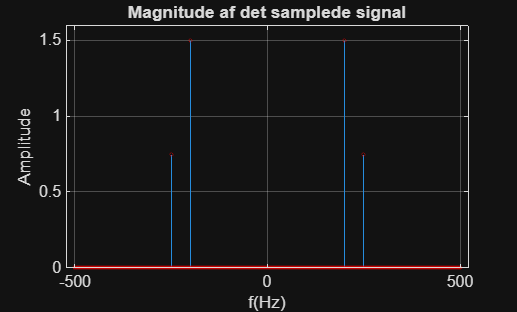


%normaliseret frekvens MEGA VIGTIG: 
f = (-N/2:N/2-1)/N;

fHz = f*Fs;
%nedenfor har jeg lavet fft samt fft shift af xa[n]
%og så plotter jeg absolut værdi af xa[n] som funktion af f*Fs
Y = fft(xan); 
X = fftshift(Y); 
stem(fHz,abs(X/N),'lineWidth',0.2,'MarkerSize',2,'MarkerEdgeColor','red') 
title('Magnitude af det samplede signal');
ylabel('Amplitude');
xlabel('f(Hz)');
%xlim([-1000,1000])
ylim([0,1.6]);
grid on; 
hold off; 


%vi kan se at vi med Fs =1000 har aliasing da vi ikke har en spike ved
%F2 = 750Hz, Fmaks= Fs/2 = 500 så vi vil se 750Hz spejlet om denne akse og
%derfor får vi en spike ved -250 og 250 i stedet pga aliasing

% svar spørgsmål 2.3 b): 
% for at undgå aliasing skal vi sample med dobbelte frekvens af den højeste
% signalfrekvens vi har og da denne er 750Hz skal vi sample med 1500Hz 


opgave 2.4

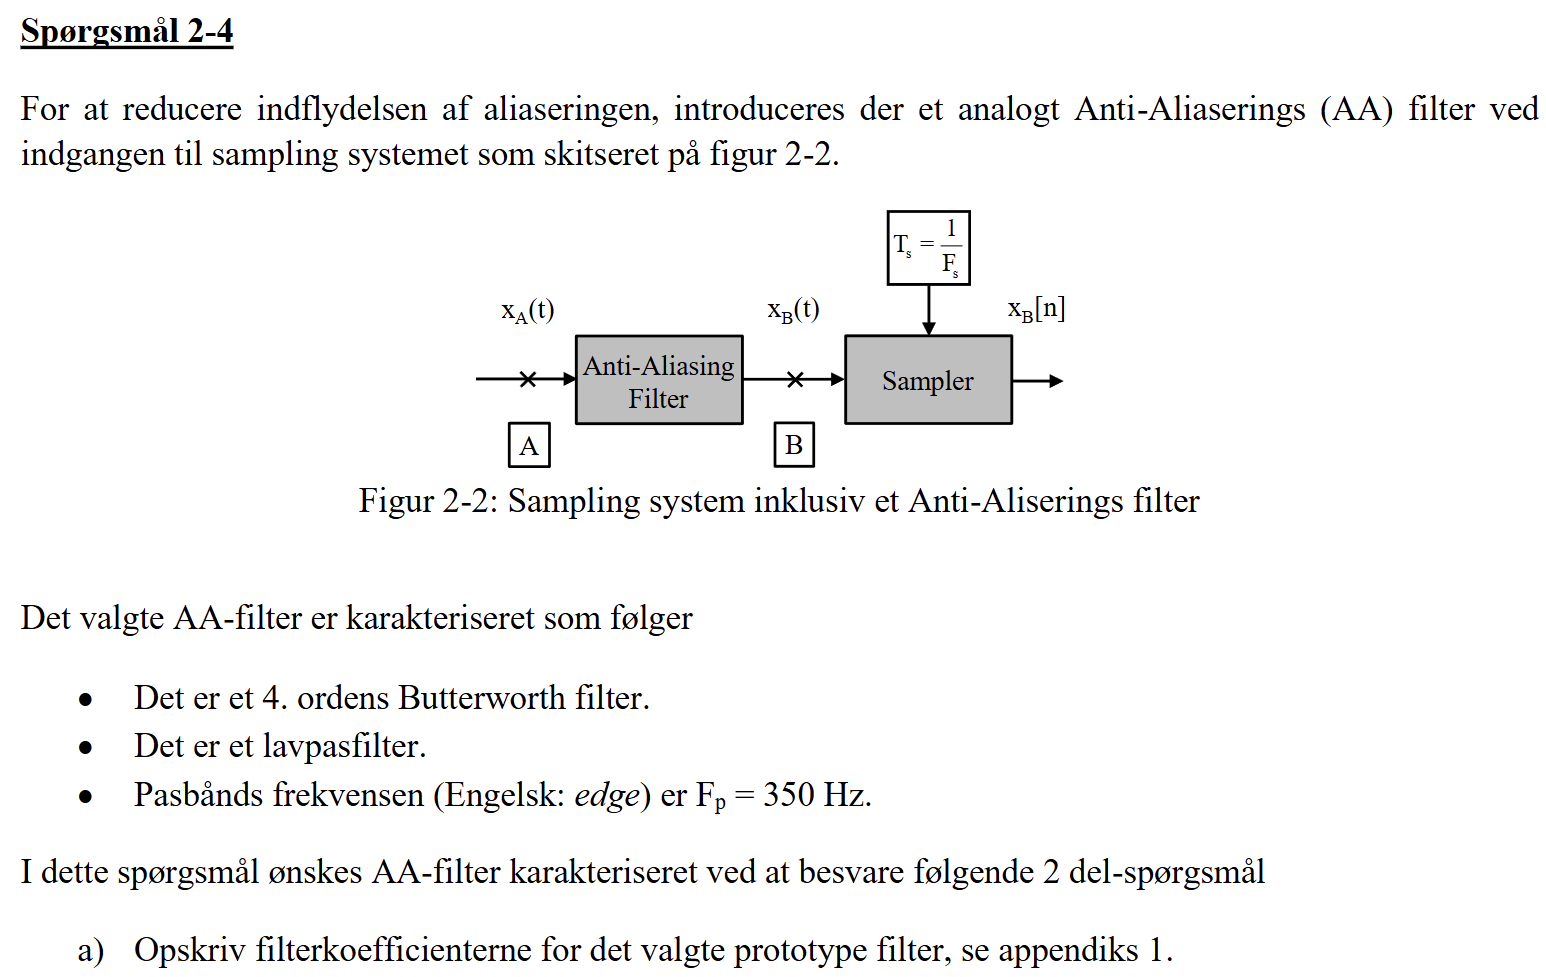

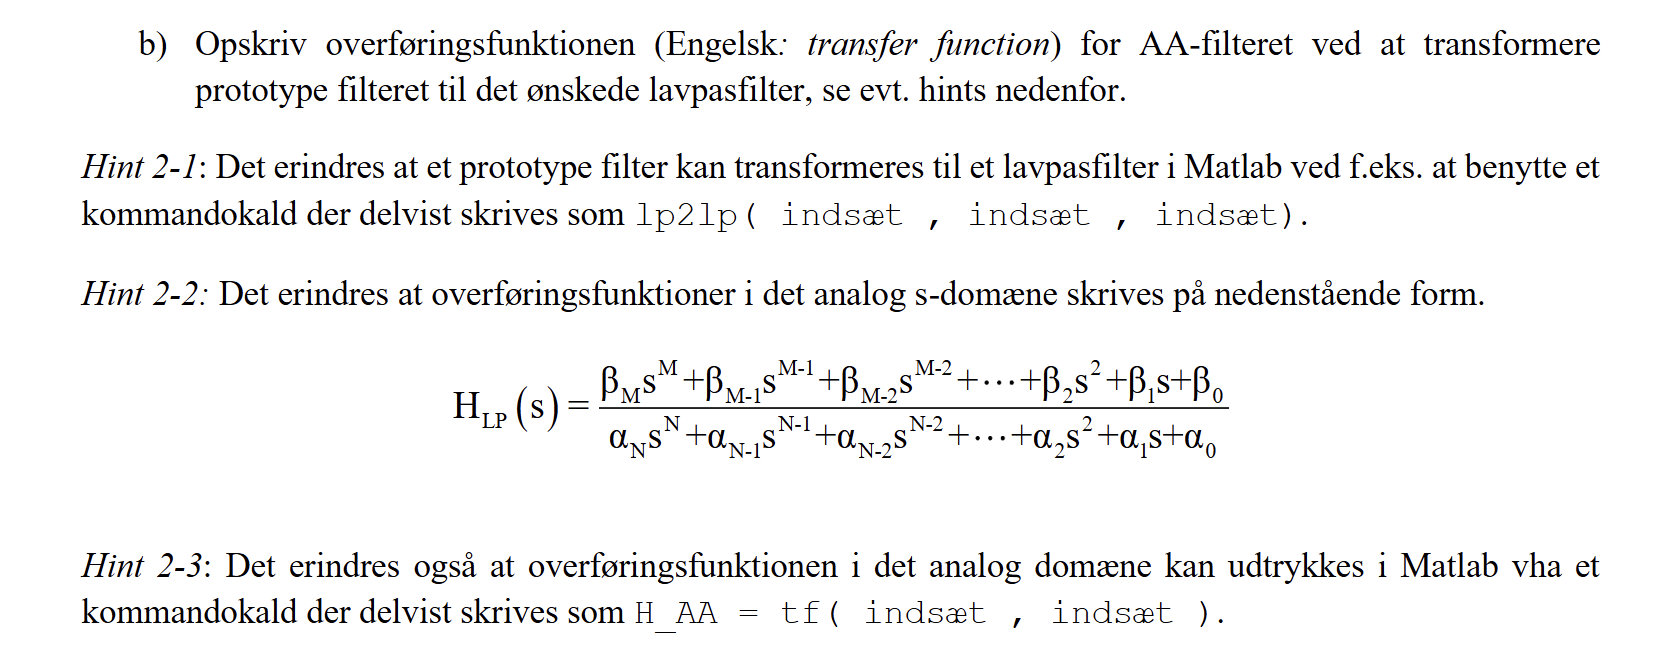

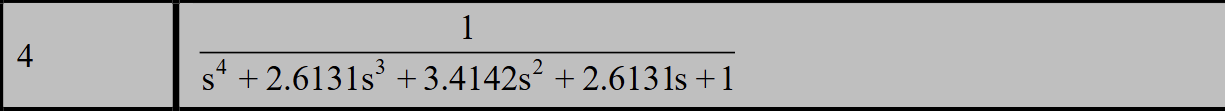


%koefficenterne kan aflæses direkte fra appendiks på sidste side. 
b = [1];
a = [1 2.6131 3.4142 2.6131 1];

%passbånd frekvens 
Fs = 350;  
Omega_ana_p  = 2*pi*Fs; 

[num, den] = lp2lp(b, a, Omega_ana_p)

num = 2.3388e+13

den = 1.0e+13 *

    0.0000    0.0000    0.0000    0.0028    2.3388


%da der er ganget 10^13 på svaret så skal jeg udskrive dem manuelt så jeg
%ikke kommer til at bruge de falske værdier (der står for eks at den(1) = 0*10^13 men den er = 1 )
n1= num(1)

n1 = 2.3388e+13

d1=den(1)

d1 = 1

d2=den(2)

d2 = 5.7465e+03

d3=den(3)

d3 = 1.6511e+07

d4=den(4)

d4 = 2.7791e+10

d5=den(5)

d5 = 2.3388e+13

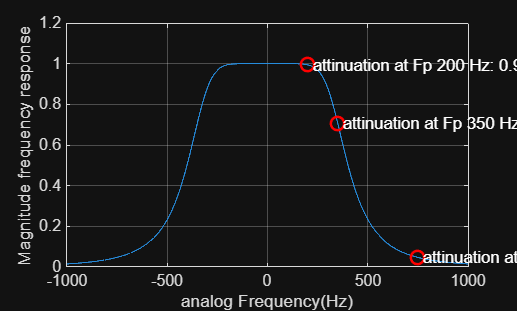


%nedenfor er den analoge frekvens sat højt da det ellers kommer til at se 
% mærkeligt ud i dette tilfælde
%OG BEMÆRK DET ER RADS 
Omegaanalog = [-100000:0.5:100000]; %analog frekvensvektor til plot
%vi har Fp opgivet i opgaven og her skal vi så med denne finde den analoge

fHz = Omegaanalog/(2*pi); %rads til Hz 

h = freqs(num,den,Omegaanalog);

plot(fHz, (abs(h)));
xlim([-1000,1000]);
xlabel('analog Frequency(Hz)')
ylabel(['Magnitude frequency response'])
grid on
hold on 

%nedenfor er bare grafisk kode som indsætter punkter ved den ønskede
%frekvens
[~, idx200] = min(abs(fHz - 200));
[~, idx350] = min(abs(fHz - 350));
[~, idx750] = min(abs(fHz - 750));
% Hent værdierne på frekvensresponsen
y200 = abs(h(idx200));
y350 = abs(h(idx350));
y750 = abs(h(idx750));
% Plot punkterne
plot(200, y200, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(350, y350, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(750, y750, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)

text(fHz(idx200), y200, ' attinuation at Fp 200 Hz: 0.994379', 'Color','white', 'FontSize',10);
text(fHz(idx350), y350, ' attinuation at Fp 350 Hz: 0.707187', 'Color','white', 'FontSize',10);
text(fHz(idx750), y750, ' attinuation at Fp 750 Hz: 0.0473698', 'Color','white', 'FontSize',10);
hold off 

Opgave 4

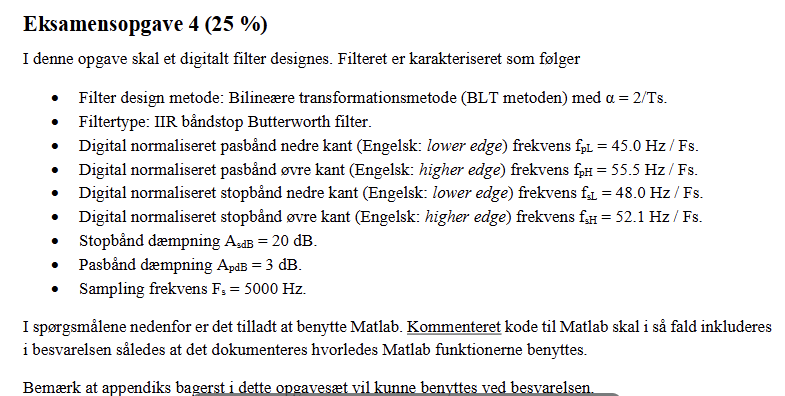

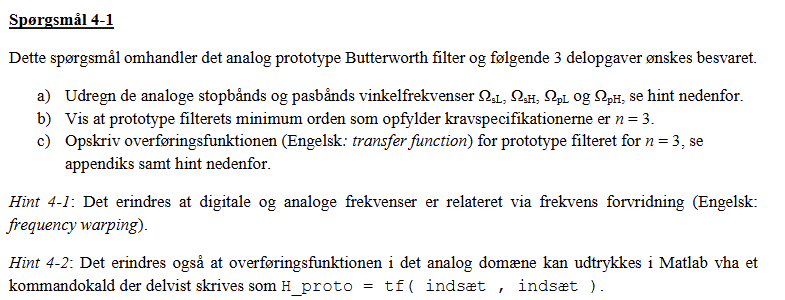

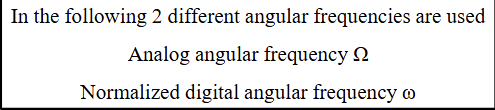

husk at lille omega er den normaliserede angulare frekvens i radianer

%vi kan se vi skal designe et stopbånd filter der cutter alt mellem 48 og
%52.1 Hz 

% vi starter med at skrive koefficenterne ind
Fs = 5000 %sampling frekvens i Hz 

Fs = 5000

% det noteres at den maksimale signalfrekvens vi kan sample korrekt på er
% 2500Hz 

Ts = 1/Fs;
alpha = 2/Ts; 

fpL = 45/Fs;  % disse 4 digitale frekvenser er opgivet i opgaven
fpH = 55.5/Fs;
fsL = 48/Fs;
fsH = 52.1/Fs;

AsdB = 20; % stopbånd dæmpning i dB 
ApdB = 3; % pasbånd dæmpning i dB 


% opgave a)
%for at kunne udregne de analoge frekvenser skal vi først lige huske at vi
%har de digitale normaliserede frekvenser i Hz, for at få lille omega skal
%vi have frekvensen i radianer (normaliseret digital frekvens i radianer)

omega_pL_dig = fpL*2*pi;
omega_pH_dig = fpH*2*pi;
omega_sL_dig = fsL*2*pi;
omega_sH_dig = fsH*2*pi;
%vi udregner de analoge vinkelfrekvenser: 
Omega_ana_pL = (2/Ts)*tan((omega_pL_dig)/2)

Omega_ana_pL = 282.8187

Omega_ana_pH = (2/Ts)*tan(omega_pH_dig/2)

Omega_ana_pH = 348.8582

Omega_ana_sL = (2/Ts)*tan(omega_sL_dig/2)

Omega_ana_sL = 301.6844

Omega_ana_sH = (2/Ts)*tan(omega_sH_dig/2)

Omega_ana_sH = 327.4709


% vi kan her se at stopbåndsgrænserne ligger klart imellem pass grænserne
% som opfylder det vi ser nedenfor: 

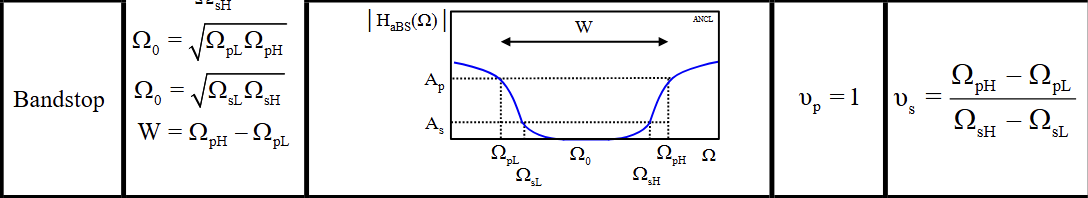

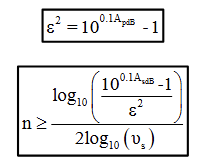

4.1 b) 

% se ovenfor hvordan vi kan udregne "new" og om ordenen er passende  "n"

new = (Omega_ana_pH-Omega_ana_pL)/(Omega_ana_sH-Omega_ana_sL)

new = 2.5610


epsilon_i_anden = 10^(0.1*ApdB)-1

epsilon_i_anden = 0.9953


n = 3; %ordenen vi skal bekræfte 
%n_test skal være mindre eller lig med n 
n_test = (log10( (  (10^(0.1*AsdB))-1 )    / ((epsilon_i_anden) )))  /( 2*log10(new))

n_test = 2.4457


% vi kan se at n_test = 2.4457 <= 3 så filterets orden er passende 

% vi opskriver overføringsfunktionen: 

b = [1];
a = [1 2 2 1];

H_overf_proto = tf(b,a)


H_overf_proto =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.


Opgave 4.2

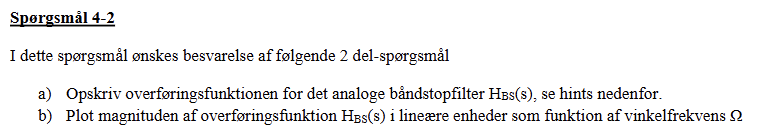

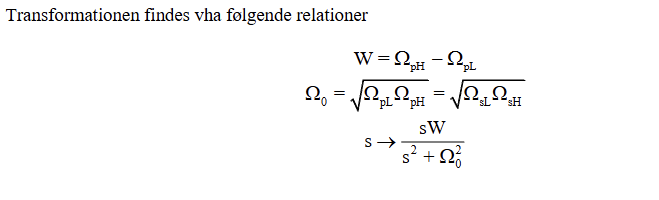

ignorerer s linjen ovenfor. det står også i s

%a) 
%andet navn så den ikke krampulerer med forrige filteropgave
Omega_analog = [0:0.1:100000]; % analog frekvens større giver bare bedre opløsning

omega0 = sqrt(Omega_ana_sL*Omega_ana_sH) % tester for sjov begge men de burde være ens 

omega0 = 314.3133

%omega1 = sqrt(Omega_ana_pL*Omega_ana_pH) % behøves ikke


omega0test = sqrt(Omega_ana_pL*Omega_ana_pH)

omega0test = 314.1077

W = Omega_ana_pH-Omega_ana_pL

W = 66.0395


[num, den] = lp2bs(b, a, omega0, W)

num = 1.0e+14 *

    0.0000         0    0.0000         0    0.0003         0    9.6422


den = 1.0e+14 *

    0.0000    0.0000    0.0000    0.0000    0.0003    0.0129    9.6422



H_BS = tf(num, den)


H_BS =
 
                      s^6 + 2.964e05 s^4 + 2.928e10 s^2 + 9.642e14
  ------------------------------------------------------------------------------------
  s^6 + 132.1 s^5 + 3.051e05 s^4 + 2.638e07 s^3 + 3.014e10 s^2 + 1.289e12 s + 9.642e14
 
Continuous-time transfer function.


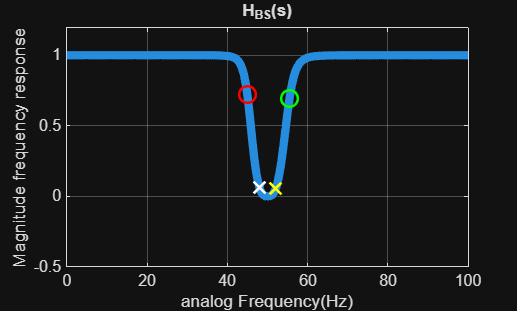


fHz2 = Omega_analog/(2*pi);
h2 = freqs(num,den,Omega_analog);

plot(fHz2, abs(h2), 'LineWidth', 5  );
xlim([0,100]);

ylim([-0.5,1.2]);
xlabel('analog Frequency(Hz)')
ylabel(['Magnitude frequency response'])
grid on
title('H_B_S(s)')
hold on  

%HUSK NEDENFOR KUN AT BRUGE HELTAL ELLERS VIL DEN IKKE KUNNE PLOTTE
%PUNKTERNE!!!!
%nedenfor er bare grafisk kode som indsætter punkter ved den ønskede
%frekvens
[~, idx45] = min(abs(fHz2 - 45));
[~, idx48] = min(abs(fHz2 - 48));
[~, idx52] = min(abs(fHz2 - 52.1));
[~, idx55] = min(abs(fHz2 - 55.5));
% Hent værdierne på frekvensresponsen
y45 = abs(h2(idx45));
y48  = abs(h2(idx48));
y52 = abs(h2(idx52));
y55 = abs(h2(idx55));

% Plot punkterne
plot(45, y45, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
plot(48, y48, 'wx', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
plot(52.1, y52, 'yx', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
plot(55.5, y55, 'go', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)

%under stjerner indsæt  ***  punktnavn eller beskrivelse
text(fHz2(idx45), y45, '   ', 'Color','white', 'FontSize',10 );
text(fHz2(idx48), y48, '   ', 'Color','white', 'FontSize',10);
text(fHz2(idx52), y52, '   ', 'Color','white', 'FontSize',10);
text(fHz2(idx55), y55, '   ', 'Color','white', 'FontSize',10);

hold off 

Opgave 4.3


% her laver vi en bilinear transformation af vores analoge
% Overføringsfunktions numinator og denominator  og laver transformerer 
[num_dig_bandstop,den_dig_bandstop] = bilinear(num,den,Fs)

num_dig_bandstop =     0.9869   -5.9097   14.7567  -19.6678   14.7567   -5.9097    0.9869


den_dig_bandstop =     1.0000   -5.9618   14.8215  -19.6675   14.6917   -5.8578    0.9740



TF_Dig_BS = filt(num_dig_bandstop,den_dig_bandstop)


TF_Dig_BS =
 
  0.9869 - 5.91 z^-1 + 14.76 z^-2 - 19.67 z^-3 + 14.76 z^-4 - 5.91 z^-5 + 0.9869 z^-6
  -----------------------------------------------------------------------------------
    1 - 5.962 z^-1 + 14.82 z^-2 - 19.67 z^-3 + 14.69 z^-4 - 5.858 z^-5 + 0.974 z^-6
 
Sample time: unspecified
Discrete-time transfer function.



fHz3 = [0:0.1:2500];

h3 = freqz(num_dig_bandstop,den_dig_bandstop,fHz3,Fs)

h3 =    1.0000 + 0.0000i   1.0000 - 0.0008i   1.0000 - 0.0017i   1.0000 - 0.0025i   1.0000 - 0.0034i   1.0000 - 0.0042i   1.0000 - 0.0050i   1.0000 - 0.0059i   1.0000 - 0.0067i   1.0000 - 0.0076i   1.0000 - 0.0084i   1.0000 - 0.0092i   0.9999 - 0.0101i   0.9999 - 0.0109i   0.9999 - 0.0118i   0.9999 - 0.0126i   0.9999 - 0.0135i   0.9999 - 0.0143i   0.9999 - 0.0151i   0.9999 - 0.0160i   0.9999 - 0.0168i   0.9998 - 0.0177i   0.9998 - 0.0185i   0.9998 - 0.0194i   0.9998 - 0.0202i   0.9998 - 0.0211i   0.9998 - 0.0219i   0.9997 - 0.0227i   0.9997 - 0.0236i   0.9997 - 0.0244i   0.9997 - 0.0253i   0.9997 - 0.0261i   0.9996 - 0.0270i   0.9996 - 0.0278i   0.9996 - 0.0287i   0.9996 - 0.0295i   0.9995 - 0.0304i   0.9995 - 0.0312i   0.9995 - 0.0321i   0.9995 - 0.0330i   0.9994 - 0.0338i   0.9994 - 0.0347i   0.9994 - 0.0355i   0.9993 - 0.0364i   0.9993 - 0.0372i   0.9993 - 0.0381i   0.9992 - 0.0390i   0.9992 - 0.0398i   0.9992 - 0.0407i   0.9991 - 0.0416i


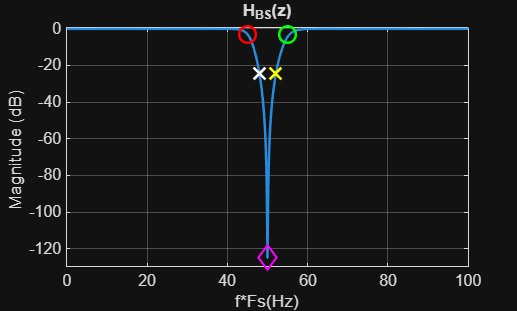


plot(fHz3, 20*log10(abs(h3)), 'LineWidth', 1.5  );
xlim([0,100]);

ylim([-130,1]);
xlabel('f*Fs(Hz)')
ylabel(['Magnitude (dB) '])
grid on
title('H_B_S(z)')
hold on  

%HUSK NEDENFOR KUN AT BRUGE HELTAL ELLERS VIL DEN IKKE KUNNE PLOTTE
%PUNKTERNE!!!!
%nedenfor er bare grafisk kode som indsætter punkter ved den ønskede
%frekvens
    [~, idx45] = min(abs(fHz3 - 45));
    [~, idx48] = min(abs(fHz3 - 48));
    [~, idx52] = min(abs(fHz3 - 52.1));
    [~, idx55] = min(abs(fHz3 - 55.5));
    [~, idx50] = min(abs(fHz3 - 50));
    
    % Hent værdierne på frekvensresponsen
    y45 = 20*log10(abs(h3(idx45)));
    y48 = 20*log10(abs(h3(idx48)));
    y52 = 20*log10(abs(h3(idx52)));
    y55 = 20*log10(abs(h3(idx55)));
    y50 = 20*log10(abs(h3(idx50)));

    % Plot punkterne
    plot(45, y45, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    plot(48, y48, 'wx', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    plot(52, y52, 'yx', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    plot(55, y55, 'go', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    plot(50, y50, 'md', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)    %under stjerner indsæt  ***  punktnavn eller beskrivelse
    %under stjerner indsæt  ***  punktnavn eller beskrivelse
    text(fHz3(idx45), y45, '   ', 'Color','white', 'FontSize',10 );
    text(fHz3(idx48), y48, '   ', 'Color','white', 'FontSize',10);
    text(fHz3(idx52), y52, '   ', 'Color','white', 'FontSize',10);
    text(fHz3(idx55), y55, '   ', 'Color','white', 'FontSize',10);
    text(fHz3(idx50), y50, '   ', 'Color','white', 'FontSize',10);

hold off 